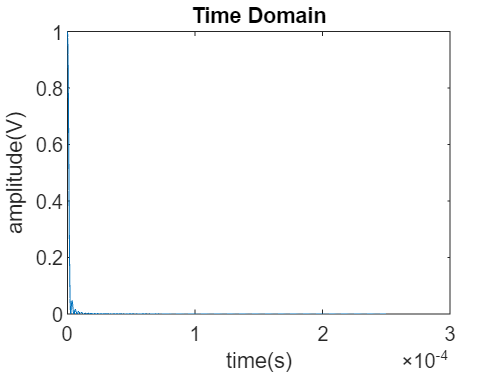

Ts=0.0000002;
fs=1/Ts;
f1=400000;
tstop=100/f1;

t=0:Ts:tstop;

x=sinc(f1*t).*sinc(f1*t);
plot(t,x);
xlabel('time(s)');
ylabel('amplitude(V)');
title('Time Domain');



f=-fs/2:f1/100:fs/2;
signal=fft(x);
signal=fftshift(signal);
plot(f,signal);

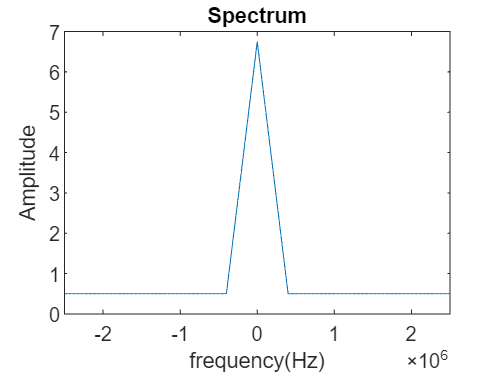

ylabel('Amplitude');
xlabel('frequency(Hz)');
title('Spectrum');

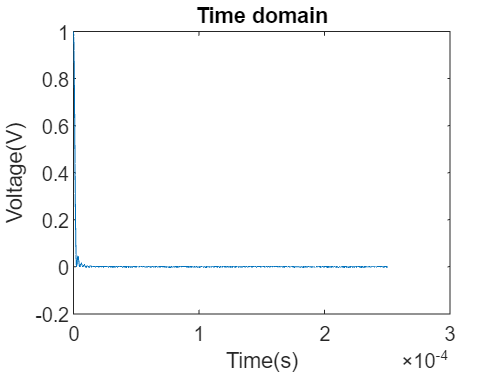



noise=0.001*randn(size(signal));
noisySignal=noise+x;
plot(t,noisySignal);
xlabel('Time(s)');
ylabel('Voltage(V)');
title('Time domain');


Signal=fft(noisySignal);
Signal=fftshift(Signal);
plot(f,Signal);

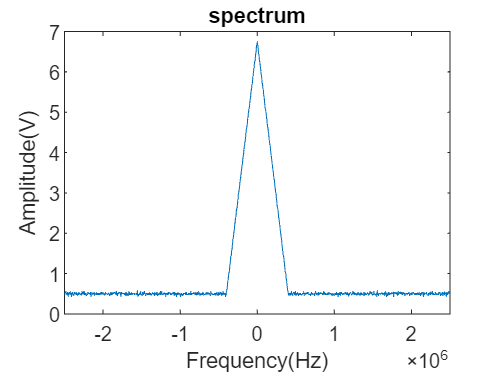

xlabel('Frequency(Hz)');
ylabel('Amplitude(V)');
title('spectrum');

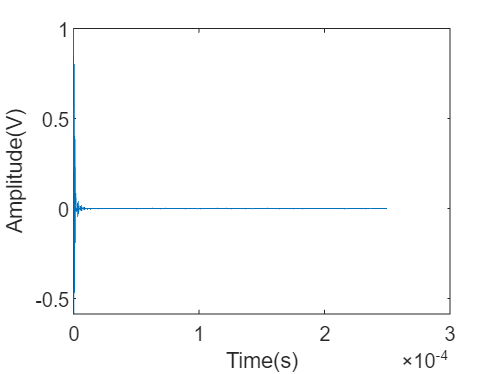


%AM formation
fc=1600000;
Ac=2;
c=Ac*cos(2*pi*fc*t);
x1=(noisySignal).*(c/Ac);
plot(t,x1);
xlabel('Time(s)');
ylabel('Amplitude(V)');

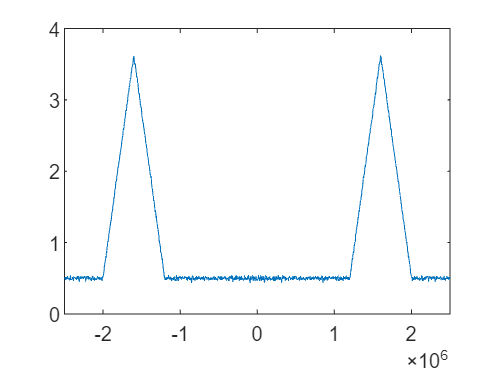


amx=fft(x1);
amx=fftshift(amx);
plot(f,amx);